Método de la potencia

% A = [4,0,0;0,3,0;0,0,1/5]
A = [1, 2, 3; 2, 4, 5; 3, 5, 6]

A =      1     2     3
     2     4     5
     3     5     6


[autovectores, autovalores] = eig(A)

autovectores =     0.7370    0.5910    0.3280
    0.3280   -0.7370    0.5910
   -0.5910    0.3280    0.7370


autovalores =    -0.5157         0         0
         0    0.1709         0
         0         0   11.3448


v = [1;17;900]

v =      1
    17
   900


lambda = potencia(A-11.3448*autovectores(:,3)*autovectores(:,3)',v)

lambda = -0.5157

Que el resultado dependa del vector inicial depende de la matriz. Si le resto lamnda1*v1*v1' obtengo el siguiente autovector más grande (teorema espectral). Lo de hacer softmax funciona solo en algunos casos. 

Método de newton

f = @(x) exp(x)*log(x) +x^3 -2

f = function_handle with value:
    @(x)exp(x)*log(x)+x^3-2


[raiz_newton,converge] = newton(f,2)

raiz_newton = 1.1553

converge = logical
   0


vpa(f(raiz_newton))

$$ans = -0.00000000000000044408920985006261616945266723633$$

Factorización LU

A = [1, 2, 3; 
     4, 5, 6; 
     7, 8, 9];
[L,U] = LU(A)

L =      1     0     0
     4     1     0
     7     2     1


$$U = \left(\begin{array}{ccc} 1 & 2 & 3\\ 0 & -3 & -6\\ 0 & 0 & 0 \end{array}\right)$$

L*U

$$ans = \left(\begin{array}{ccc} 1 & 2 & 3\\ 4 & 5 & 6\\ 7 & 8 & 9 \end{array}\right)$$

Método de Jacobi 

A = [0.5, 0.3; 0.1, 0.4];
b = [1; 2];
x0 = [0;1]

x0 =      0
     1


[xs,converge]= jacobi(A,b,x0)

xs =    -1.1765
    5.2941


converge = logical
   1


linsolve(A, b)

ans =    -1.1765
    5.2941


Para que un método iterativo funcione, su radio espectral debe ser menor que uno.

Método de Gauss-Seidel

A = [0.5, 0.3; 0.1, 0.4];
b = [1; 2];
x0 = [0;1]

x0 =      0
     1


[xs,converge]= gauss_seidel(A,b,x0)

xs =    -1.1765
    5.2941


converge = logical
   1


linsolve(A, b)

ans =    -1.1765
    5.2941


Factorización Cholesky 

A = [6,15,55;15,55,225;55,225,979]

A =      6    15    55
    15    55   225
    55   225   979


L =cholesky(A)

L =     2.4495         0         0
    6.1237    4.1833         0
   22.4537   20.9165    6.1101


L*L'

ans =     6.0000   15.0000   55.0000
   15.0000   55.0000  225.0000
   55.0000  225.0000  979.0000


Euler para resolver PVI

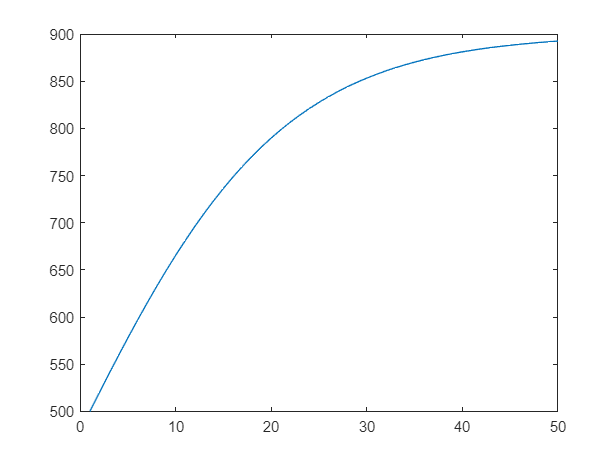

xx = linspace(1,50,50);
f = @(x,y) 0.1*y*(1-(y/1000)) -0.01*y; % ojo con los * 
f(1,1);
alpha =500;
yy = euler(f,xx,alpha);
plot(xx,yy)

RK2 para resolver PVI

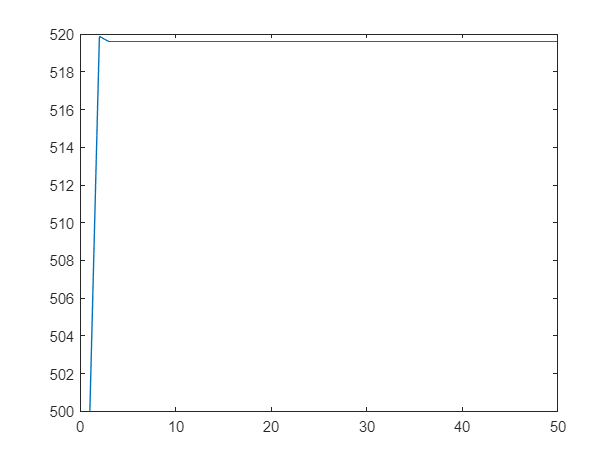

xx = linspace(1,50,50);
f = @(x,y) 0.1*y*(1-(y/1000)) -0.01*y; % ojo con los * 
f(1,1);
alpha =500;
yy = rk2(f,xx,alpha);
plot(xx,yy)

Fórmula del rectángulo compuesta

f = @(x) x.^2 % si te dicen que las cosas son matrices ponemos puntos

f = function_handle with value:
    @(x)x.^2


integral(f,-1,1)

ans = 0.6667

rectangulo(f,-1,1)

ans = 0.6668

Método del punto medio compuesto

f = @(x) x.^2 % si te dicen que las cosas son matrices ponemos puntos

f = function_handle with value:
    @(x)x.^2


integral(f,-1,1)

ans = 0.6667

ptomedio(f,-1,1)

ans = 0.6666

Método del trapecio compuesto

f = @(x) x.^2 % si te dicen que las cosas son matrices ponemos puntos

f = function_handle with value:
    @(x)x.^2


integral(f,-1,1)

ans = 0.6667

trapecio(f,-1,1)

ans = 0.6668

Método de simpson 1/3 compuesto

f = @(x) x.^2 % si te dicen que las cosas son matrices ponemos puntos

f = function_handle with value:
    @(x)x.^2


integral(f,-1,1)

ans = 0.6667

simpson13(f,-1,1)

ans = 0.6712

Interpolación con Newton

syms x
f = symfun(x^9 + x^8 + x^2 + sin(x) +9,x)

$$f(x) = \sin\left(x\right)+x^{2}+x^{8}+x^{9}+9$$

xx = linspace(1,10,5);
pol = expand(newton_interpolate(f,xx))

$$pol = \frac{44330\,\sin\left(1\right)}{19683}-\frac{1727868235163\,x}{8192}+\frac{4433\,\sin\left(10\right)}{19683}+\frac{16120\,\sin\left(\frac{11}{2}\right)}{6561}-\frac{54560\,\sin\left(\frac{13}{4}\right)}{19683}-\frac{22880\,\sin\left(\frac{31}{4}\right)}{19683}-\frac{31853\,x\,\sin\left(1\right)}{19683}-\frac{7175\,x\,\sin\left(10\right)}{19683}-\frac{24772\,x\,\sin\left(\frac{11}{2}\right)}{6561}+\frac{76976\,x\,\sin\left(\frac{13}{4}\right)}{19683}+\frac{36368\,x\,\sin\left(\frac{31}{4}\right)}{19683}+\frac{2674\,x^{2}\,\sin\left(1\right)}{6561}-\frac{848\,x^{3}\,\sin\left(1\right)}{19683}+\frac{32\,x^{4}\,\sin\left(1\right)}{19683}+\frac{1090\,x^{2}\,\sin\left(10\right)}{6561}-\frac{560\,x^{3}\,\sin\left(10\right)}{19683}+\frac{32\,x^{4}\,\sin\left(10\right)}{19683}+\frac{3332\,x^{2}\,\sin\left(\frac{11}{2}\right)}{2187}-\frac{1408\,x^{3}\,\sin\left(\frac{11}{2}\right)}{6561}+\frac{64\,x^{4}\,\sin\left(\frac{11}{2}\right)}{6561}-\frac{8464\,x^{2}\,\sin\left(\frac{13}{4}\right)}{6561}+\frac{3104\,x^{3}\,\sin\left(\frac{13}{4}\right)}{19683}-\frac{128\,x^{4}\,\sin\left(\frac{13}{4}\right)}{19683}-\frac{5296\,x^{2}\,\sin\left(\frac{31}{4}\right)}{6561}+\frac{2528\,x^{3}\,\sin\left(\frac{31}{4}\right)}{19683}-\frac{128\,x^{4}\,\sin\left(\frac{31}{4}\right)}{19683}+\frac{811439865247\,x^{2}}{8192}-\frac{73033001915\,x^{3}}{4096}+\frac{563490137\,x^{4}}{512}+\frac{526739314929}{4096}$$

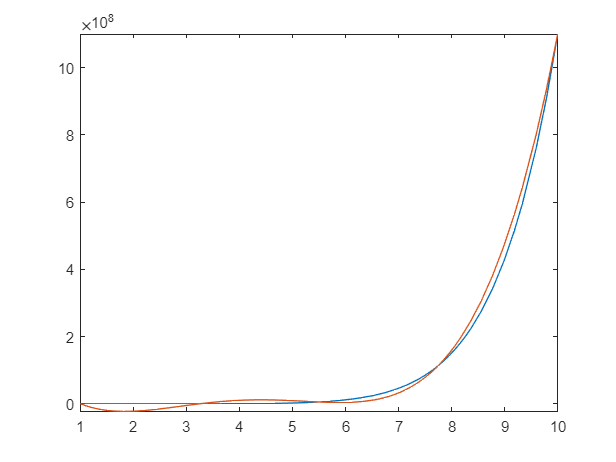


figure
fplot(f,[1,10])
hold on
fplot(pol,[1,10])

Problema 6 Repaso 1

f = @(t) 1/t

f = function_handle with value:
    @(t)1/t


aprox = simpson13(f,1,2)

aprox = 0.6940

abs(log(2)-aprox) < 1e-3 % con 999 puntos vale 

ans = logical
   1
